# PRÁCTICA 1 CÁLCULO NUMÉRICO

28-02-2023

**Grupo 8: **Ana Robledano Abasolo, Alfredo Robledano Abasolo, 

                Melani Tatayo Culchas, Rubén Sierra Serrano.

# **Ejercicio 1 (Corregido)**

## T2.1 Búsqueda de raices 

a) Escribe una función de Matlab para obtener un intervalo de ancho `dx` que 

contenga una raíz de la función 𝑓(𝑥) partiendo de un intervalo (𝑎,𝑏) con 𝑎 < 𝑏 

Nombra a la función: $function   [x1, x2] = raizbus(fun, a, b, dx) $ donde: 

$fun =$ función en forma anónima $fun = @(x) $

$\left(a,b\right)=$ intervalo de inicio de búsqueda 

$\textrm{dx}=$ ancho del intervalo 

$[x1, x2] =$  intervalo de ancho dx donde se encuentra una raíz de 𝑓(𝑥) 

-   Véase raizbus.m

b) Escribe una función de Matlab que obtenga las abscisas de los intervalos 

donde se encuentran todas las raices de una función 𝑓(𝑥) en un intervalo dado 

(𝑎,𝑏) llamando a la función `raizbus` creada anteriormente. 

Nómbrala: $\textrm{function}\;x=\textrm{raices}\left(\textrm{fun},a,b,\textrm{dx}\right)$

$x$ es una matriz de 2 columnas cuyas filas son las abscisas de los extremos de los intervalos donde se encuentra la raíz. Las otras variables se corresponden con las de la función `raizbus.` Modifica la función `raizbus` de modo que en lugar de dar el aviso, asigne $\textrm{x1}=\textrm{x2}=\textrm{NaN}\ldotp$

-  Véase raices.m 

c) Emplea la función anterior y la función `bisección` (si no la has creado en 

clase, deberás hacerlo ahora, para ello sigue las indicaciones de los ejercicios de clase) para calcular las raices del polinomio $x^3 -10x^2 +5\;\textrm{con}\;\textrm{dx}=0\ldotp 001$. 

Emplea previamente el comando `roots` de Matlab para establecer el intervalo de búsqueda inicial (𝑎,𝑏) y comprobar el resultado obtenido (las raíces). Emplea el comando `rmmissing` para eliminar los valores NaN de la matriz de resultados de la función `raices`. Toma $\textrm{dx}=0\ldotp 001$ y una tolerancia en la función bisección que sea coherente con ese valor de $\textrm{dx}$`. `Da los resultados en una lista en la que las columnas correspondan a las raíces calculadas, las dadas por Matlab y el error relativo en %. 

Limpieza del workspace y salidas:

clear, clc

Declaramos la función, el tamaño del intervalo y un vector con los coeficientes de la función.

f = @(x) x.^3 - 10*x.^2 + 5;
dx = 0.001;
p = [1 -10 0 5];

Dibujamos la función para hacernos una idea del problema a resolver.

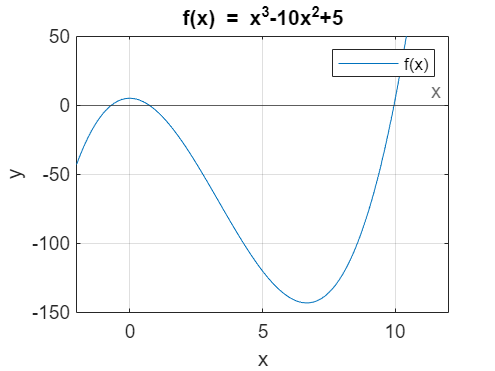

x = linspace(-2, 12);
plot(x, f(x))
hold on
yline(0, '-', 'x')
ylim([-150, 50])
xlim([-2, 12])
ylabel('y')
xlabel('x')
title("f(x) = x^{3}-10x^{2}+5");
legend('f(x)')
grid
hold off

A continuación, se halla las raices del polinomio con el comando `roots.`

sol_matlab = sort(roots(p));
% Se convierte en tabla los datos obtenidos
tabla_sol_matlab = table(num2str(sol_matlab, "%.4f"), 'VariableNames', "SOLUCIONES MATLAB");
disp("Las soluciones que da matlab son:")

Las soluciones que da matlab son:


disp(tabla_sol_matlab)

    SOLUCIONES MATLAB
    _________________

         -0.6841     
          0.7346     
          9.9495     



Para obtener los intervalos se usa la función `raices. Con el intervalo inicial que vemos en la gráfica (a,b) = (-0.7, 10).`

x = raices(f, -0.7, 10, dx);
% Se convierte los datos obtenido en tabla
tabla_intervalos = table( ...
    num2str(x(:, 1), "%.4f"), ...
    num2str(x(:, 2), "%.4f"), ...
    VariableNames={'x1', 'x2'});
disp("Con la función raices se han encontrado los siguientes intervalos (x1, x2)")

Con la función raices se han encontrado los siguientes intervalos (x1, x2)


disp(tabla_intervalos)

      x1         x2   
    _______    _______

    -0.6850    -0.6840
     0.7340     0.7350
     9.9490     9.9500



Con la función `bisección `calculamos las soluciones aproximadas en los intervalos obtenidos.

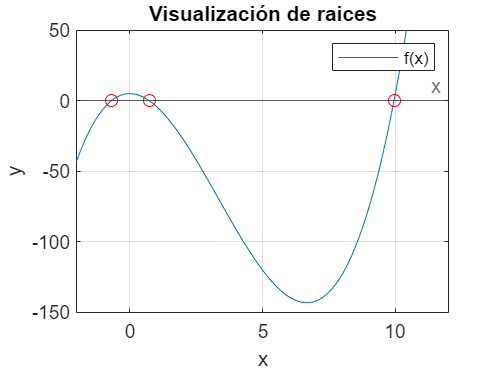

% Tamaño del vector de las raices
n = size(sol_matlab);
sol_biseccion = zeros(n);
error_rel = zeros(n);
error_biseccion = 1e-5; % Tomaremos un error menor que el dx
% Este bucle usa la función biseccion para hallar las raices  a la vez que se haya el error relativo 
for i = 1: n
    sol_biseccion(i)= biseccion(f,x(i,1),x(i,2), error_biseccion) ;  
    error_rel(i) = abs((sol_matlab(i)- sol_biseccion(i))/sol_matlab(i))*100;
end
% Dibujamos las soluciones obtenidas
x = linspace(-2, 12);
plot(x, f(x))
hold on
yline(0, '-', 'x')
plot(sol_biseccion, f(sol_biseccion), 'ro')
ylim([-150, 50])
xlim([-2, 12])
ylabel('y')
xlabel('x')
legend('f(x)')
title("Visualización de raices")
grid
hold off

% Se crea una tabla para mostrar el resultado final
tabla_resultados = table( ...
    num2str(sol_biseccion, '%.5f'), ...
    num2str(sol_matlab, '%.5f'), ...% Con 5 decimales para observar la variación
    num2str(error_rel, '%.4f %%'), ... % Calculado de manera porcentual en el bucle anterior
    VariableNames=["SOLUCIÓN APROXIMADA","SOLUCIÓN MATLAB","ERROR (%)"]);
disp("Resultados obtenidos:")

Resultados obtenidos:


disp(tabla_resultados)

    SOLUCIÓN APROXIMADA    SOLUCIÓN MATLAB    ERROR (%)
    ___________________    _______________    _________

         -0.68409             -0.68409        0.0000 % 
          0.73460              0.73460        0.0000 % 
          9.94949              9.94949        0.0000 % 



#### Corrección ejercicio 1

- Modificado raices.m, se evita x = [ ] haciendo x = [Nan, Nan].

- No se puede tomar 1e-3 como error cuando dx es ese, tendrá que ser más pequeño que dx (se toma 1e-5).

# **Ejercicio 2 (Correcto)**

## T2.2 Método de Ridder

a) Escribe una función de Matlab que emplee el método de Ridder para buscar la  raíz de una función en un intervalo. Nómbrala: $function   [r, i] = ridder(fun, x1, x2, tol) $ donde:

$fun =$ función en forma anónima $fun = @(x) $

$\left(x_1 ,\;x_2 \right)=$ intervalo donde se encuentra la raíz.

$tol =$ tolerancia calculada como $|\;x_i -x_{i-1} \;|$

$i =$ número de iteraciones

$r = $ raíz encontrada.

- Véase ridder.m

b) Se desea calcular la raíz de la función: 


$$f\left(x\right)=\frac{1}{{\left(x-0\ldotp 3\right)}^2 +0\ldotp 01}-\frac{1}{{\left(x-0\ldotp 8\right)}^2 +0\ldotp 04}$$


Declaramos la función.

clear, clc 
f = @(x) 1 ./ ((x-0.3).^2 + 0.01) - 1 ./ ((x-0.8).^2 + 0.04);

**b.1)** Dibuja la función en las proximidades de  $x=0$ para determinar el intervalo  aproximado $\left(x_1 ,{\;x}_2 \right)$ donde se encuentra la raíz. 

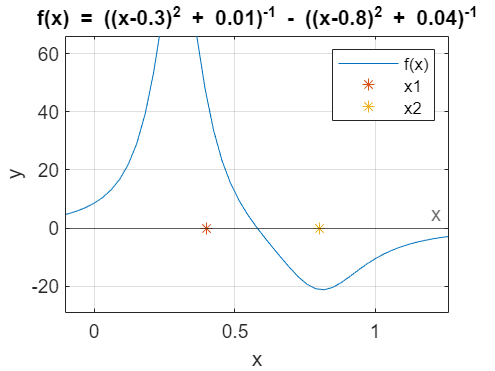

x = linspace(-1, 2);
pf = plot(x, f(x));
title("f(x) = ((x-0.3)^2 + 0.01)^{-1} - ((x-0.8)^2 + 0.04)^{-1}");
hold on
px1 = plot(0.4,0, "*");
px2 = plot(0.8,0, "*");
ylabel('y')
xlabel('x')
yline(0, '-', 'x')
xlim([-0.10 1.26])
ylim([-29 66])

legend([pf px1 px2], ["f(x)" "x1" "x2"])
grid
hold off

Tomamos el intervalo $\left(x_1 ,{\;x}_2 \right)=\left(0\ldotp 4,\;0\ldotp 8\right)$  al que pertenece la raíz.

x1 = 0.4; x2 = 0.8;

**b.2)** Calcula la raíz empleando la función del apartado a) con un error menor que ${10}^{-6}$. Indica también el número de iteraciones empleadas.

ermax = 1e-6;
[r, i] = ridder(f, x1, x2, ermax);
fprintf("La raíz es %.7f", r);

La raíz es 0.5800000

fprintf("Se han requerido %d iteraciones", i);

Se han requerido 7 iteraciones

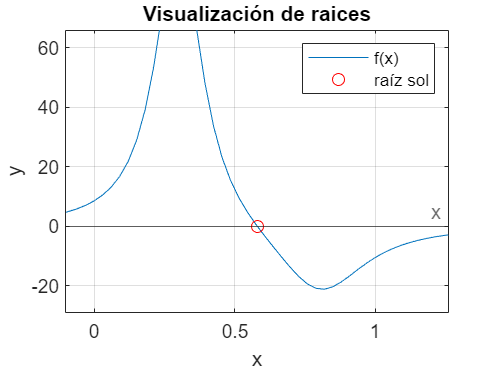


pf2 = plot(x, f(x));
hold on
pr = plot(r, f(r), 'ro');
title("Visualización de raices")
ylabel('y')
xlabel('x')
yline(0, '-', 'x')
xlim([-0.10 1.26])
ylim([-29 66])
legend([pf2 pr], ["f(x)" "raíz sol"]);
grid
hold off

# **Ejercicio 3**

## T2.3 Método de Muller 

a) Escribe una función de Matlab que calcule las raices de un polinomio mediante 

el método de Müller. 

Nombra a la función: $r = Muller(fun,a,b, ermax)$ donde: 

$\textrm{fun}$= función dada en forma anónima $f=@\left(x\right)$

$(a, b)

$ = intervalo donde se encuentra la raíz 

$\textrm{ermax}$ = error máximo 

- Veáse Muller.m

La función debe comenzar calculando los valores de `fun` en `a, b` y el punto 

medio del intervalo `(a, b``)` que tomará como  $x_0 ,x_{1\;} \;y\;\;x_2$ respectivamente. 

### Apartado b)

Resuelve mediante la función anterior el siguiente problema: 

Al tratar de encontrar la acidez de una solución de hidróxido de magnesio en 

ácido clorhídrico, se obtiene la ecuación siguiente: 

𝐴(𝑥) = $x^3 -3\ldotp 5x^2 -40$ 

donde x es la concentración del ion hidronio. Calcule la concentración del ion 

hidronio para una solución saturada (cuando la acidez es igual a cero). Dibuja 

previamente la función para aproximar el intervalo donde se encuentra la raíz. 

Da la respuesta con un error menor que ${10}^{-6}$. Comprueba el resultado con el comando `roots` de Matlab y verifica si el error es el esperado. 

Limpieza del workspace y salidas:

clear, 
close all;

Definición de la función objetivo:

f = @(x) x.^3 - 3.5.*x.^2 - 40;

Dibujamos la función para hacernos una idea del problema a resolver.

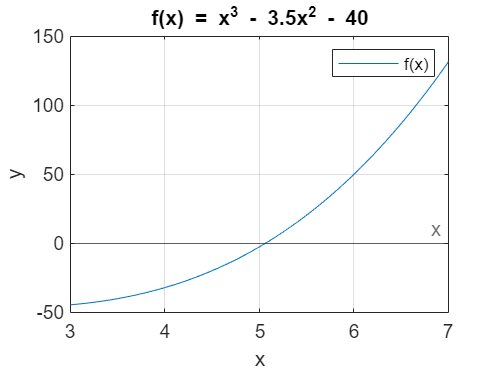

x = linspace(3, 7);
plot(x, f(x))
hold on
yline(0, '-', 'x')
ylabel('y')
xlabel('x')
title("f(x) = x^{3} - 3.5x^{2} - 40");
legend('f(x)')
grid
hold off

Calculamos la raíz con Muller() eligiendo a ojo un intervalo adecuado por ejemplo el (4, 6)

error = 1e-6;
raiz = Muller(f, 4, 6, error);
fprintf("La raíz obtenida es: %.7f",raiz)

La raíz obtenida es: 5.0614100

Dibujamos los resultados:

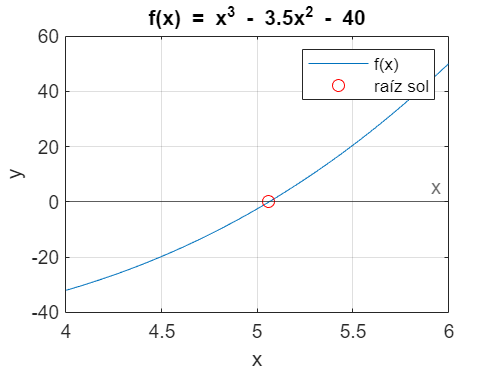

x = linspace(4, 6);
plot(x, f(x))
hold on
plot(raiz, f(raiz), 'ro');
yline(0, '-', 'x')
ylabel('y')
xlabel('x')
title("f(x) = x^{3} - 3.5x^{2} - 40");
legend("f(x)","raíz sol")
grid
hold off

Realizamos una comparación con los resultados de matlab:

p = [1 -3.5 0 -40];
raices_matlab = roots(p)

raices_matlab =    5.0614 + 0.0000i
  -0.7807 + 2.7006i
  -0.7807 - 2.7006i


Al dar varias soluciones con parte imaginaria solo mantenemos la que es un número real.

raiz_matlab = raices_matlab(imag(raices_matlab)==0);
fprintf('La raíz real que da Matlab es: %.7f', raiz_matlab)

La raíz real que da Matlab es: 5.0614100

Veamos el error entre ellas:

error = raiz_matlab - raiz;
fprintf("El error entre la solución de matlab y la que da Muller es:\n %e", error);

El error entre la solución de matlab y la que da Muller es:
 -4.294343e-12

Como era de esperar el error es pequeño.

#### Corrección ejercicio 3

# Ejercicio 4

### T2.4 Método de Newton para resolver sistemas de ecuaciones no lineales

### Apartado a)

Escribe una función de Matlab que resuelva un sistema de ecuaciones no lineales mediante el método de Newton-Raphson. Nombra a la función: r = nrsis(funs,x,ermax)

- Véase nrsis.m

### Apartado b)

Emplea la función nrsis para calcular las soluciones del sistema de ecuaciones:


$$\sin \left(x\right)+y^2 +\ln \left(z\right)-7=0$$



$$3x+2^y -z^3 +1=0$$



$$x+y+z-5=0$$


Con un error de ${10}^{-5}$, comienza las iteraciones con $x_0$ = [1 1 1].

Comprueba el resultado verificando que las raices encontradas cumplen las ecuaciones con un error menor que el especificado.

Limpieza del workspace y salidas:

clear, clc

Inicialización de las variables de entrada:

syms x y z
f1 = sin(x) + y^2 - log(z) - 7;
f2 = 3*x + 2^y - z^3 + 1;
f3 = x + y + z - 5;

Se almacena en el vector columna funs las funciones simbólicas (representan las ecuaciones del sistema igualadas a cero).

funs = [f1; f2; f3];
disp('Ecuaciones no lineales del sistema (están igualadas a cero)')

Ecuaciones no lineales del sistema (están igualadas a cero)


disp(funs)

$$\left(\begin{array}{c} y^{2}-\log\left(z\right)+\sin\left(x\right)-7\\ -z^{3}+3\,x+2^{y}+1\\ x+y+z-5 \end{array}\right)$$

error = 1e-5;  
x0 = [1, 1, 1]; % Se pide que se comiencen las iteraciones en este x0

Calculamos la solución del sistema de ecuaciones no lineal llamando a la función nrsis().

xns = nrsis(funs, x0, error);
fprintf("La solución aproximada del sistema de ecuaciones es");

La solución aproximada del sistema de ecuaciones es

fprintf("x = %.6f\ny = %.6f\nz = %.6f", xns(1), xns(2), xns(3))

x = 0.236534
y = 2.733779
z = 2.029687

Comprobemos que la solución cumple las ecuaciones con un error menor que el especificado:

errores_ecuaciones = eval(subs(funs, [x, y, z], xns))

errores_ecuaciones = 1.0e-15 *

    0.2220
   -0.8882
   -0.2220


Observamos que el error es del orden de ${10}^{-15}$ en todas las ecuaciones.

Siendo mucho menor que el error utilizado.

# Ejercicio 5

### T2.5 Método de Newton-Raphson modificado para el cálculo de raices múltiples

a) Escribe una función de Matlab que calcule la raíz de una función mediante el método de Newton-Raphson modificado de acuerdo con el algoritmo explicado anteriormente. Nombra a la función [xs,i] = newtonmod (f,xest,ermax)

- Véase newtonmod.m

b) Emplea la función anterior para calcular las raices del polinomio: 


$$f\left(x\right)=x^3 -5x^2 +7x-3$$


Comenzando con xest = 0 y ermax = 1e-5

Haz lo mismo con la función newtonraphson de los ejercicios de clase. Compara los resultados.

Desarrollo:

Limpieza del workspace, y salidas.

clear, clc

Declaramos las variables de entrada.

syms x
f = x^3 - 5*x^2 + 7*x - 3;
xest = 0;
ermax = 1e-5;

Dibujamos la función para hacernos una idea del problema que estamos resolviendo.

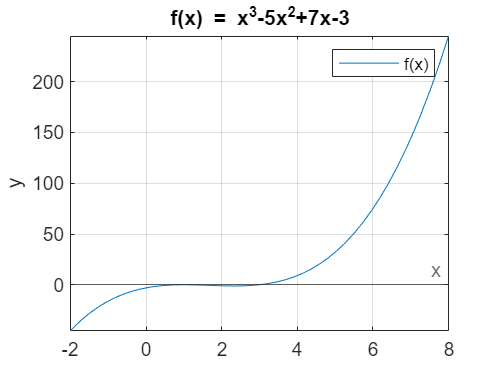

fplot(f, [-2, 8])
hold on
yline(0, '-', 'x')
legend('f(x)')
title("f(x) = x^{3}-5x^{2}+7x-3")
ylabel('y')
xlabel('x')
grid
hold off

Calculamos la raíz próxima a cero con ambos métodos.

% Función Newton-Raphson modificada
[r_mod, i_mod] = newtonmod(f, xest, ermax);
% Función de clase
[r_clase, i_clase] = newton_raphson_tol_sol(f, xest, ermax);

Mostramos los resultados con 6 decimales.

fprintf("Raíz método clase: %.6f", r_clase);

Raíz método clase: 0.999994

fprintf("Se han requerido %d iteraciones.", i_clase);

Se han requerido 18 iteraciones.

fprintf("Raíz método modificado: %.6f", r_mod);

Raíz método modificado: 1.000000

fprintf("Se han requerido %d iteraciones.", i_mod);

Se han requerido 4 iteraciones.

Gráficamente:

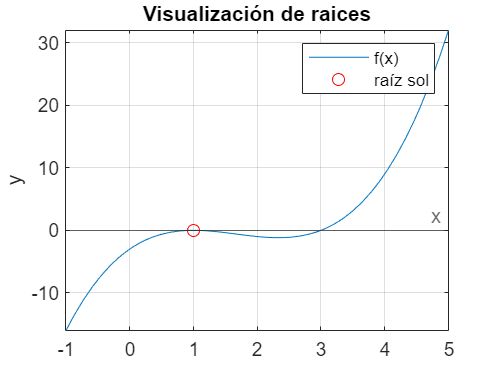

pf = fplot(f, [-1, 5]);
fx = matlabFunction(f);
hold on
px = plot(r_mod, fx(r_mod), 'ro');
yline(0, '-', 'x')
legend([pf px],"f(x)","raíz sol");
title("Visualización de raices");
ylabel('y')
xlabel('x')
grid
hold off

Calculamos la diferencia relativa entre los dos métodos:

dif_r = abs((r_mod - r_clase) / r_clase) * 100;
fprintf("Las raices calculadas difieren en un %.4f%%", dif_r);

Las raices calculadas difieren en un 0.0006%

Conclusión:

El método modificado requiere de menos iteraciones y obtiene mayor precisión en el problema planteado.